# what's a convolution

It's a combination between a signal and a kernel

for each t, the signal is dot-product multiplied with the sliding kerne

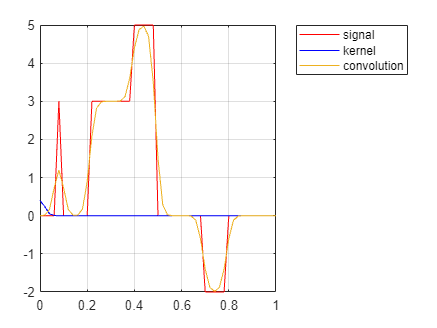

clear;

time = linspace(-1,1,101);

% an arbitrary signal with some rectangular features
signal = zeros(size(time)); 
signal(55)=3;
signal(time>0.20 & time <0.40)=3;
signal(time>=0.40 & time <0.50)=5;
signal(time>0.70 & time < 0.80)=-2;

% an arbitrary signal, eg. a gaussian with normalized sum to keep the
% signal at the same amplitude
kernel = normpdf(time,0,0.02); kernel=kernel/sum(kernel);


figure;
plot(time,signal,'r',DisplayName="signal");
hold on;
plot(time,kernel,'b',DisplayName="kernel");

% by using same, we keep the center part rather than n+m-1
% Mike X Cohen explains why n+m-1: https://youtu.be/9Hk-RAIzOaw?si=4JmPvc0oI7CvA9ye&t=1082
signal_conv = conv(signal,kernel,"same");
hold on;
plot(time,signal_conv,DisplayName="convolution");
legend("show",Location="bestoutside")
grid on;
xlim([0 1]);